# ThrowDice

A Monte Carlo experiment simulating dice throw results.

Throw a number of dice and sum the upwards faces. Repeat, say, 100,000 times. Histogram the resulting sums building a histogram from scratch, rather than using [histogram](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html).

Author: Duncan Carlsmith

Set the number of dice to throw.

**Try this**: Change the number of dice, or equivalently the number of throws of a single die to use in an experiment.

numberOfThrows = 5;

Create empty bins for histogram.

histcounts = zeros(numberOfThrows*6, 1);

Pick number of experiments.

numberOfExperiments = 100000;

Initialize array to hold the result of each experiment.

sumOfThrows=zeros(numberOfExperiments,1);

Loop over experiments.

for rolls = 1 : numberOfExperiments    

Throw the dice and [sum](https://www.mathworks.com/help/matlab/ref/sum.html) the numbers on the upwards faces. [randi](https://www.mathworks.com/help/matlab/ref/randi.html) returns a vector of random numbers, each an integer from 1 to 6, to represent the values on the upperwards faces. The length of the vector is the number of dice thrown.

	throws = randi(6, numberOfThrows, 1);
	sumOfThrows(rolls) = sum(throws);

Increment the result count in the appropriate histogram bin.

	histcounts(sumOfThrows(rolls)) = histcounts(sumOfThrows(rolls)) + 1;
end

Make a figure, add a [bar](https://www.mathworks.com/help/matlab/ref/bar.html) plot of the counts in the histogram array, and ladd abels.

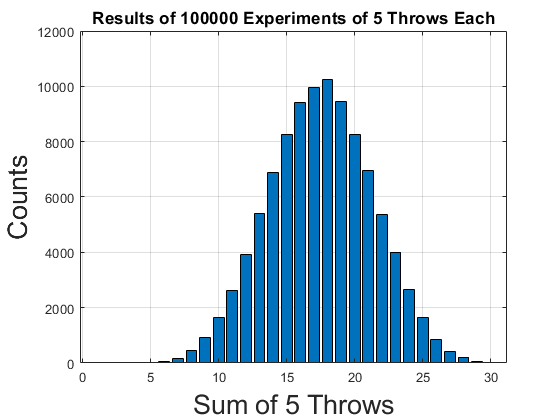

figure
bar(histcounts);
grid on;
caption = sprintf('Results of %d Experiments of %d Throws Each', ...
	numberOfExperiments, numberOfThrows);
title(caption, 'FontSize', 13);
caption = sprintf('Sum of %d Throws', numberOfThrows);
xlabel(caption, 'FontSize', 20);% note: you have font size control
ylabel('Counts', 'FontSize', 20);